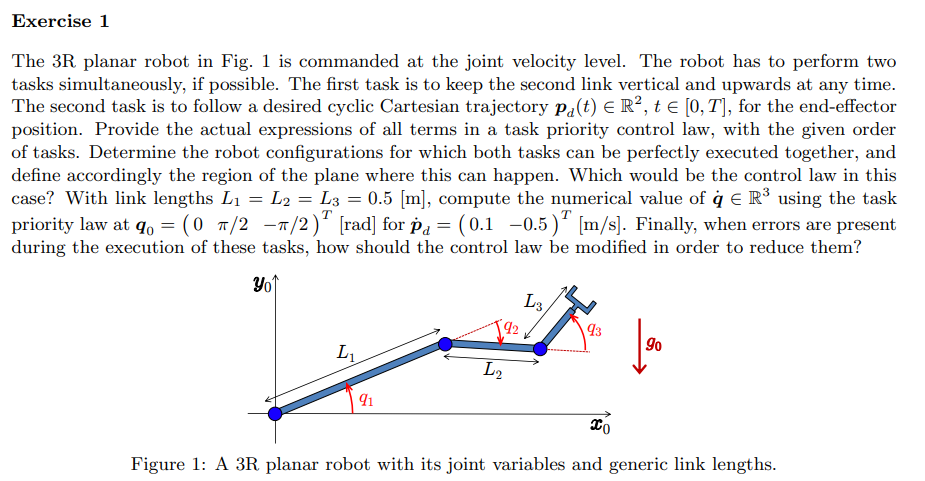

% % This part is isolated from previous section
% clear;clc
% 
% % syms k q1(t) q2(t) q3(t)
% sigma = [0,0,0];
% R2Robot=['rrr';'xxx';[1,1,1]]    
% n = length(sigma);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% q_d= sym('q_d_', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% % 
% dc = sym('dc_', [n 1],'real');
% % k = sym('k', [n 1],'real');
% l = sym('l_', [n 1],'real');
% m = sym('m_', [n 1],'real');
% % m_p = sym('m_p','real');
% % m(2)=m(2)+m_p
% I = sym('I_', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,-g0,0]';
% 
% 
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1
% % z.dhTable=[]
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% % z.opt_expr={[l(1)+q(2)],[q(2)]};
% % z.rcdefined=true;
% z.joint_on=false;

## torque regulation catesian

% % % z_regulation_torque=Join_Torque_Control_Law_Regulation(z)
% % 

## using Cartesian dynamics control LAw

% % 
% % % z_regulation_torque=cartesian_dynamics_Control_Law_Regulation(z)
% % 

## dynamic model computation neccessary for the control law

% % z.task_defined={struct('Pc',q(1)+q(2),'f',sum([q(1),q(2),0]))} %pc is note necessary
% % z.taskpositions=struct('main',2,'remain',[1])
% pd={sym('pd_1_',[1,1],'real'),sym('pd_2_',[2,1],'real')};
% z.task_defined={struct('f',sum([q(1),q(2),0]),'pd_',pd{1},'pd_dot_',[0]),struct('f','end_effector','pd_',pd{2},'pd_dot_',[0.1,-0.5]')} %pc is note necessary
% z.xyonly=false %% should be false if we wnat to add new tasks

% 
% [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot,PC_EE]= getGenericPC_EE2(z);

% f
% PCVar.f_dot
% PCVar.f_ddot
% PCVar.f_tdot
% PC_EEShort.J

% rank(PC_EEShort.J)

% 
% % f(3)=
% % xyonly=true
% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE(R2Robot,l,q,qd,dc,m,I,xyonly)
% % VarShortRobot.M
% % angle_desired=[0,0]
% % l(1)=0
% % [Pc,vc,w,T,Ti,M,VarShortRobot,Trans] = getGenericPC2(z);
% % Trans.Jacobian_PTotal
% % Trans.Jacobian_dot_PTotal
% % [C,cac,Csubs,S] = getCs(M,q,q_dot);
% % cac

## rank of J

% rank(J)

% rd_1=f(1,:)
% rd_2=f(2:end,:)

## redundancy task with prioriy

% replace_values=true
% % vars2replace=[z.q;z_q_dot_k,z.]
% z.q_=[0,pi/2,-pi/2]'
% 
% [q_dot_k,z_task] = Redundancy_tasks_with_Priority(z,PC_EE,replace_values);
% 

## seein varaibles

% q_dot_k{:}
% z_task.J_k{:}
% z_task.J_k_pinv{:}
% z_task.P_A_k{:}
% 
% z_task.q_dot_k_{:}
% z_task.J_k_{:}
% z_task.J_k_pinv_{:}
% z_task.P_A_k_{:}

% r_dot_k=z_task.r_dot_k
% simplify(subs(q_dot_k{2},r_dot_k{1},0))
% simplify(simplify(pinv((z_task.J_k{2}*z_task.P_A_k{1})))*z_task.r_dot_k{2})
% 

## cheking if is possible do both tasks

% f_k_red=simplify(subs(z_task.f_k{2},q(1)+q(2),pi/2))
% q_red=[q(1),q(3)]'
% q_dot_red=[q_dot(1),q_dot(3)]'
% J_k_red=jacobian(f_k_red,q_red)
% q_dot_=q_dot;
% q_dot_(2)=-q_dot_(1)

## singularities

% simplify(det(J_k_red)) %%singular in q_1-q_3=m*pi/2 where m>0

## replacing values

% q_=[0,pi/2,-pi/2]'
% l_=[0.5,0.5,0.5]'
% r_dot_k=[z_task.r_dot_k{1};z_task.r_dot_k{2}]
% r_dot_k_=[0,0.1,-0.5]'
% vars2replace =[q ;l;r_dot_k]
% vars2replace_=[q_;l_;r_dot_k_]
% q_dot_k{2}
% q_dot_k_=subs(z_task.q_dot_k_{2},vars2replace,vars2replace_)
% term1_=subs(z_task.J_k{2}*z_task.P_A_k{1},vars2replace,vars2replace_)
% pinv(term1_)

## replacing singular values into each jacobian

% z_task.J_k{1}*q_dot_k_ %% equal to zero it means that the task can be done
% 
% subs(z_task.J_k{2}*q_dot_k_,[q;l],[q_;l_] )%% in this case it is different of the pd_dot_2 then this task s not possible to realize only with an minimization error result


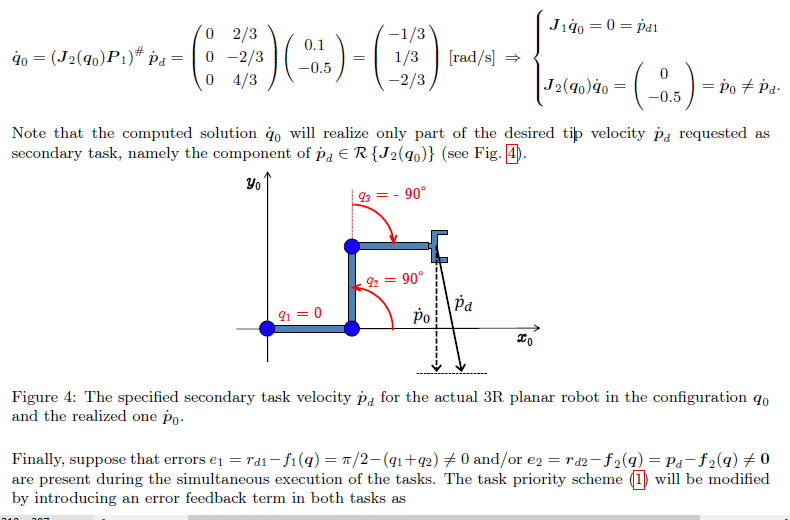

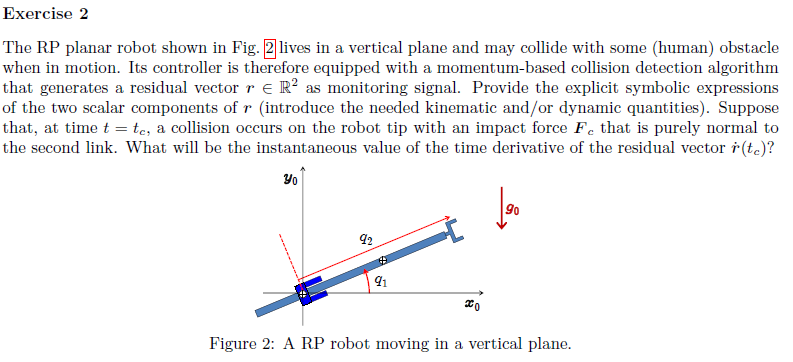

% % This part is isolated from previous section
% clear;clc;
% 
% % syms k q1(t) q2(t) q3(t)
% sigma = [0,1]; %% rot=0 prismatic=1
% n = length(sigma);
% % t = sym('t', 'real');
% q = sym('q', [n 1],'real');
% q_d= sym('q_d', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% % 
% dc = sym('dc', [n 1],'real');
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% % m(2)=m(2)+m_p;
% I = sym('I', [n 1],'real');
% alpha_angle=sym('alpha','real');
% g0 = sym('g0','real');
% 
% R2Robot=['rp';'xx';[1,1]]    

R2Robot = 3×2 char array
    'rp'
    'xx'
    ''


% 
% z = Gen_param(n);
% z.g=[0,-g0,0]';
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1;
% % z.dhTable=[]
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% % z.opt_expr={[l(1)+q(2)],[q(2)]};
%  z.opt_expr={[l(1),dc(1)],[0,0]};
% % z.rcdefined=true;

## defining collisions

% 
% % collide1=
% F_0=sym('F_0','real')

$$F\_0 = F_{0}$$

% F=sym('F_',[3,1],'real')

$$F = \left(\begin{array}{c} F_{1}\\ F_{2}\\ F_{3} \end{array}\right)$$

% % z.collides=[struct('F',F_0*[-sin(q(1)),cos(q(1)),0]' ,'joint',2,'F_pos',l(2)*0), %%position force taken from the base in this case on the EE
% z.collides=[struct('F',F ,'joint',2,'F_pos',l(2)*0), %%position force taken from the base in this case on the EE
% %             struct('F',[0,-1,0]' ,'joint',1,'F_pos',l(1)),
% %             struct('F',[0, 1,0]' ,'joint',2,'F_pos',l(2)/2)
%             ];
% z.collides(1)

ans = struct with fields:
        F: [3×1 sym]
    joint: 2
    F_pos: [1×1 sym]


## computing

% 
% % 
% %    
% % % xyonly=true
% % % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGtenericPC_EE(R2Robot,l,q,qd,dc,m,I,xyonly)
% % % VarShortRobot.M
% % % angle_desired=[0,0]
% % % l(1)=0
% z.q_=[pi/2,-pi/2]';
% z.q_dot_=[0,pi/4]';
% z.l_=[1,1;]';
% z.prismatic_CoM_method=[1,2]

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: [2×1 double]
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: [2×1 double]
                  q_dot_: [2×1 double]
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: {[1×2 sym]  [0 0]}
                collides: [1×1 struct]
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 2]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
        

% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans,zout] = getCollisions(z)

rcdefined = logical
   1


z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: [2×1 double]
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: [2×1 double]
                  q_dot_: [2×1 double]
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: {[1×2 sym]  [0 0]}
                collides: [1×1 struct]
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 2]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
        

si falla aquí está el error


$$a = l_{1}$$

d = 0

anglerot = 1×2 cell array
    {4×4 sym}    {4×4 sym}


method with PC , pay attention!
moving frames OFF!!


$$Ti = \frac{I_{1}\,{{\dot{q}}_{1}}^{2}}{2}$$

moving frames OFF!!


$$Ti = \left(\begin{array}{cc} \frac{I_{1}\,{{\dot{q}}_{1}}^{2}}{2} & \frac{m_{2}\,\left(\left({{\mathrm{dc}}_{2}}^{2}-2\,{\mathrm{dc}}_{2}\,q_{2}+{q_{2}}^{2}\right)\,{{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{I_{2}\,{{\dot{q}}_{1}}^{2}}{2} \end{array}\right)$$

$$To\_derive = \left(\begin{array}{cc} -q_{2}\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\\ q_{2}\,\cos\left(q_{1}\right) & \sin\left(q_{1}\right)\\ 0 & 0 \end{array}\right)$$

$$q\_t = \left(\begin{array}{c} q_{1}\left(t\right)\\ q_{2}\left(t\right) \end{array}\right)$$

    "check the _ last term it is needed for the function for example q_1_ should be the right way to define a varaible to convert to time dependent"



z_derivated = struct with fields:
    dot_t: [3×2 sym]


z_derivated = struct with fields:
     dot_t: [3×2 sym]
    ddot_t: [3×2 sym]


z_derivated = struct with fields:
     dot_t: [3×2 sym]
    ddot_t: [3×2 sym]
    tdot_t: [3×2 sym]


z_derivated = struct with fields:
        dot_t: [3×2 sym]
       ddot_t: [3×2 sym]
       tdot_t: [3×2 sym]
          dot: [3×2 sym]
    dot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
        dot_t: [3×2 sym]
       ddot_t: [3×2 sym]
       tdot_t: [3×2 sym]
          dot: [3×2 sym]
    dot_short: []


z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []


z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []
          tdot: [3×2 sym]
    tdot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []
          tdot: [3×2 sym]
    tdot_short: []


moving frames OFF!!


$$Vc\_T\_dot\_Fk = F_{1}\,\left({\dot{q}}_{2}\,\cos\left(q_{1}\right)-q_{2}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right)\right)+F_{2}\,\left({\dot{q}}_{2}\,\sin\left(q_{1}\right)+q_{2}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right)\right)$$

$$Tau\_c = \left(\begin{array}{c} F_{2}\,q_{2}\,\cos\left(q_{1}\right)-F_{1}\,q_{2}\,\sin\left(q_{1}\right)\\ F_{1}\,\cos\left(q_{1}\right)+F_{2}\,\sin\left(q_{1}\right) \end{array}\right)$$

zout = struct with fields:
    J_c_collisions_: {[3×2 sym]}


>> Getting  the Christoffel’sym. Might take a while...
*** Computation of Potential Energy (Jacobian-based method) 


$$qall\_sincos\_comb = \left(\begin{array}{cccccc} \sin\left(q_{1}\right) & \sin\left(q_{2}\right) & \sin\left(q_{1}+q_{2}\right) & \cos\left(q_{1}\right) & \cos\left(q_{2}\right) & \cos\left(q_{1}+q_{2}\right) \end{array}\right)$$

$$PE = -g_{0}\,m_{2}\,\sin\left(q_{1}\right)\,\left({\mathrm{dc}}_{2}-q_{2}\right)$$

$$PE\_short = -g_{0}\,m_{2}\,s_{1}\,\left({\mathrm{dc}}_{2}-q_{2}\right)$$

$$g\_q\_short = \left(\begin{array}{c} -c_{1}\,g_{0}\,m_{2}\,\left({\mathrm{dc}}_{2}-q_{2}\right)\\ g_{0}\,m_{2}\,s_{1} \end{array}\right)$$

zout = struct with fields:
    J_c_collisions_: {[3×2 sym]}
                  C: {[2×2 sym]  [2×2 sym]}
                cac: [2×1 sym]
              Csubs: {[2×2 sym]  [2×2 sym]}
                  S: [2×2 sym]
                g_q: [2×1 sym]
                 PE: [1×1 sym]
                  U: {[1×1 sym]  [1×1 sym]}
          g_q_short: [2×1 sym]
           PE_short: [1×1 sym]


zout = struct with fields:
    J_c_collisions_: {[3×2 sym]}
                  C: {[2×2 sym]  [2×2 sym]}
                cac: [2×1 sym]
              Csubs: {[2×2 sym]  [2×2 sym]}
                  S: [2×2 sym]
                g_q: [2×1 sym]
                 PE: [1×1 sym]
                  U: {[1×1 sym]  [1×1 sym]}
          g_q_short: [2×1 sym]
           PE_short: [1×1 sym]


zout = struct with fields:
    J_c_collisions_: {[3×2 sym]}
                  C: {[2×2 sym]  [2×2 sym]}
                cac: [2×1 sym]
              Csubs: {[2×2 sym]  [2×2 sym]}
                  S: [2×2 sym]
                g_q: [2×1 sym]
                 PE: [1×1 sym]
                  U: {[1×1 sym]  [1×1 sym]}
          g_q_short: [2×1 sym]
           PE_short: [1×1 sym]


zout = struct with fields:
    J_c_collisions_: {[3×2 sym]}
                  C: {[2×2 sym]  [2×2 sym]}
                cac: [2×1 sym]
              Csubs: {[2×2 sym]  [2×2 sym]}
                  S: [2×2 sym]
                g_q: [2×1 sym]
                 PE: [1×1 sym]
                  U: {[1×1 sym]  [1×1 sym]}
          g_q_short: [2×1 sym]
           PE_short: [1×1 sym]


zout = struct with fields:
    J_c_collisions_: {[3×2 sym]}
                  C: {[2×2 sym]  [2×2 sym]}
                cac: [2×1 sym]
              Csubs: {[2×2 sym]  [2×2 sym]}
                  S: [2×2 sym]
                g_q: [2×1 sym]
                 PE: [1×1 sym]
                  U: {[1×1 sym]  [1×1 sym]}
          g_q_short: [2×1 sym]
           PE_short: [1×1 sym]


$$Pc = \left(\begin{array}{cc} 0 & -\cos\left(q_{1}\right)\,\left({\mathrm{dc}}_{2}-q_{2}\right)\\ 0 & -\sin\left(q_{1}\right)\,\left({\mathrm{dc}}_{2}-q_{2}\right)\\ 0 & 0 \end{array}\right)$$

$$vc = \left(\begin{array}{cc} 0 & {\dot{q}}_{2}\,\cos\left(q_{1}\right)+{\dot{q}}_{1}\,\sin\left(q_{1}\right)\,\left({\mathrm{dc}}_{2}-q_{2}\right)\\ 0 & {\dot{q}}_{2}\,\sin\left(q_{1}\right)-{\dot{q}}_{1}\,\cos\left(q_{1}\right)\,\left({\mathrm{dc}}_{2}-q_{2}\right)\\ 0 & 0 \end{array}\right)$$

$$w = \left(\begin{array}{cc} 0 & 0\\ 0 & -{\dot{q}}_{1}\\ {\dot{q}}_{1} & 0 \end{array}\right)$$

$$T = \frac{m_{2}\,\left(\left({{\mathrm{dc}}_{2}}^{2}-2\,{\mathrm{dc}}_{2}\,q_{2}+{q_{2}}^{2}\right)\,{{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{I_{1}\,{{\dot{q}}_{1}}^{2}}{2}+\frac{I_{2}\,{{\dot{q}}_{1}}^{2}}{2}$$

$$Ti = \left(\begin{array}{cc} \frac{I_{1}\,{{\dot{q}}_{1}}^{2}}{2} & \frac{m_{2}\,\left(\left({{\mathrm{dc}}_{2}}^{2}-2\,{\mathrm{dc}}_{2}\,q_{2}+{q_{2}}^{2}\right)\,{{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{I_{2}\,{{\dot{q}}_{1}}^{2}}{2} \end{array}\right)$$

$$M = \left(\begin{array}{cc} m_{2}\,{{\mathrm{dc}}_{2}}^{2}-2\,m_{2}\,{\mathrm{dc}}_{2}\,q_{2}+m_{2}\,{q_{2}}^{2}+I_{1}+I_{2} & 0\\ 0 & m_{2} \end{array}\right)$$

VarShortRobot = struct with fields:
    Pc: [3×2 sym]
    vc: [3×2 sym]
     w: [3×2 sym]
     T: [1×1 sym]
    Ti: [1×2 sym]
     M: [2×2 sym]


Trans = struct with fields:
                 TTotal: [4×4 sym]
                PTotali: [3×2 sym]
               TPartial: {[4×4 sym]  [4×4 sym]}
                 RTotal: [3×3 sym]
               RPartial: {[3×3 sym]  [3×3 sym]}
                 PTotal: [3×1 sym]
        Jacobian_PTotal: [3×2 sym]
    Jacobian_dot_PTotal: [3×2 sym]
               PPartial: {[3×1 sym]  [3×1 sym]}
                     Pc: [3×2 sym]
                RTotali: {[3×3 sym]  [3×3 sym]}
           ThetaPartial: [2×1 sym]
             ThetaTotal: [1×1 sym]
                     vc: [3×2 sym]
                      w: [3×2 sym]
                      T: [1×1 sym]
                     Ti: [1×2 sym]
                      M: [2×2 sym]


zout = struct with fields:
    J_c_collisions_: {[3×2 sym]}
                  C: {[2×2 sym]  [2×2 sym]}
                cac: [2×1 sym]
              Csubs: {[2×2 sym]  [2×2 sym]}
                  S: [2×2 sym]
                g_q: [2×1 sym]
                 PE: [1×1 sym]
                  U: {[1×1 sym]  [1×1 sym]}
          g_q_short: [2×1 sym]
           PE_short: [1×1 sym]
      Pc_collisions: [3×1 sym]
      vc_collisions: [3×1 sym]
     J_c_collisions: {[3×2 sym]}
        Vc_T_dot_Fk: [1×1 sym]
              Tau_c: [2×1 sym]
                p_r: [2×1 sym]
                tau: [2×1 sym]
                  r: [2×1 sym]
                P_0: [2×1 sym]
       to_integrate: [2×1 sym]
     Pc_collisions_: [3×1 sym]
     vc_collisions_: [3×1 sym]
       Vc_T_dot_Fk_: [1×1 sym]
             Tau_c_: [2×1 sym]


% F([2,3])=0

$$F = \left(\begin{array}{c} F_{1}\\ 0\\ 0 \end{array}\right)$$

% Trans.RTotal*F

$$ans = \left(\begin{array}{c} F_{1}\,\sin\left(q_{1}\right)\\ -F_{1}\,\cos\left(q_{1}\right)\\ 0 \end{array}\right)$$

% jacobian(Pc(:,2),z.q)

$$ans = \left(\begin{array}{cc} -q_{2}\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\\ q_{2}\,\cos\left(q_{1}\right) & \sin\left(q_{1}\right)\\ 0 & 0 \end{array}\right)$$

% 
% 
% M

$$M = \left(\begin{array}{cc} m_{2}\,{{\mathrm{dc}}_{2}}^{2}-2\,m_{2}\,{\mathrm{dc}}_{2}\,q_{2}+m_{2}\,{q_{2}}^{2}+I_{1}+I_{2} & 0\\ 0 & m_{2} \end{array}\right)$$

% Ti

$$Ti = \left(\begin{array}{cc} \frac{I_{1}\,{{\dot{q}}_{1}}^{2}}{2} & \frac{m_{2}\,\left(\left({{\mathrm{dc}}_{2}}^{2}-2\,{\mathrm{dc}}_{2}\,q_{2}+{q_{2}}^{2}\right)\,{{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{I_{2}\,{{\dot{q}}_{1}}^{2}}{2} \end{array}\right)$$

% J_c_collisions=zout.J_c_collisions{:}

$$J\_c\_collisions = \left(\begin{array}{cc} -q_{2}\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\\ q_{2}\,\cos\left(q_{1}\right) & \sin\left(q_{1}\right)\\ 0 & 0 \end{array}\right)$$

% J_c_collisions_=zout.J_c_collisions_{:}

$$J\_c\_collisions\_ = \left(\begin{array}{cc} \frac{\pi }{2} & 0\\ 0 & 1\\ 0 & 0 \end{array}\right)$$

% Pc_collisions=zout.Pc_collisions

$$Pc\_collisions = \left(\begin{array}{c} q_{2}\,\cos\left(q_{1}\right)\\ q_{2}\,\sin\left(q_{1}\right)\\ 0 \end{array}\right)$$

% zout.vc_collisions

$$ans = \left(\begin{array}{c} {\dot{q}}_{2}\,\cos\left(q_{1}\right)-q_{2}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right)\\ {\dot{q}}_{2}\,\sin\left(q_{1}\right)+q_{2}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right)\\ 0 \end{array}\right)$$

% zout.Vc_T_dot_Fk

$$ans = F_{1}\,\left({\dot{q}}_{2}\,\cos\left(q_{1}\right)-q_{2}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right)\right)+F_{2}\,\left({\dot{q}}_{2}\,\sin\left(q_{1}\right)+q_{2}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right)\right)$$

% zout.Tau_c

$$ans = \left(\begin{array}{c} q_{2}\,\left(F_{2}\,\cos\left(q_{1}\right)-F_{1}\,\sin\left(q_{1}\right)\right)\\ F_{1}\,\cos\left(q_{1}\right)+F_{2}\,\sin\left(q_{1}\right) \end{array}\right)$$

% vc_=subs(vc,q,z.q_)

$$vc\_ = \left(\begin{array}{cc} 0 & {\dot{q}}_{1}\,\left({\mathrm{dc}}_{2}+\frac{\pi }{2}\right)\\ 0 & {\dot{q}}_{2}\\ 0 & 0 \end{array}\right)$$

% 
% %% check formula and complete with this parameters
% zout.p_r

$$ans = \left(\begin{array}{c} {\dot{q}}_{1}\,\left(m_{2}\,{{\mathrm{dc}}_{2}}^{2}-2\,m_{2}\,{\mathrm{dc}}_{2}\,q_{2}+m_{2}\,{q_{2}}^{2}+I_{1}+I_{2}\right)\\ m_{2}\,{\dot{q}}_{2} \end{array}\right)$$

% % zout.tau
% zout.to_integrate

$$ans = \left(\begin{array}{c} r_{1}+\tau_{1}+g_{0}\,m_{2}\,\cos\left(q_{1}\right)\,\left({\mathrm{dc}}_{2}-q_{2}\right)\\ -m_{2}\,\left({\mathrm{dc}}_{2}-q_{2}\right)\,{{\dot{q}}_{1}}^{2}+r_{2}+\tau_{2}-g_{0}\,m_{2}\,\sin\left(q_{1}\right) \end{array}\right)$$

% zout.r

$$ans = \left(\begin{array}{c} r_{1}\\ r_{2} \end{array}\right)$$

% zout.P_0

$$ans = \left(\begin{array}{c} P_{0,1}\\ P_{0,2} \end{array}\right)$$

% zout.S

$$ans = \left(\begin{array}{cc} -m_{2}\,{\dot{q}}_{2}\,\left({\mathrm{dc}}_{2}-q_{2}\right) & -m_{2}\,{\dot{q}}_{1}\,\left({\mathrm{dc}}_{2}-q_{2}\right)\\ m_{2}\,{\dot{q}}_{1}\,\left({\mathrm{dc}}_{2}-q_{2}\right) & 0 \end{array}\right)$$

% zout.g_q

$$ans = \left(\begin{array}{c} -g_{0}\,m_{2}\,\cos\left(q_{1}\right)\,\left({\mathrm{dc}}_{2}-q_{2}\right)\\ g_{0}\,m_{2}\,\sin\left(q_{1}\right) \end{array}\right)$$

% % zout.cac
% % zout.S
% % % [C,cac,Csubs,S] = getCs(M,q,q_dot);
% % % cac

## computing gravity

% % % isMotor=false
% % % [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, q, l, m, dc, g, isMotor)

% % zout.U{:}
% % zout.g_q

% %  u_subs = M*q_ddot +zout.cac+ zout.g_q 

## computing the residuals r_d

%  %the nominal r_d chould be eual to 0 (no collision)
%  k_i=sym('k_i_',[2,1],'real')

$$k\_i = \left(\begin{array}{c} k_{i,1}\\ k_{i,2} \end{array}\right)$$

%  r_c_sym=sym('r_c_',[2,1],'real')

$$r\_c\_sym = \left(\begin{array}{c} r_{c,1}\\ r_{c,2} \end{array}\right)$$

%  tau_c_sym=sym('tau_c_',[2,1],'real')

$$tau\_c\_sym = \left(\begin{array}{c} \tau_{c,1}\\ \tau_{c,2} \end{array}\right)$$

%  r_dot_c=k_i.*(tau_c_sym-r_c_sym)

$$r\_dot\_c = \left(\begin{array}{c} -k_{i,1}\,\left(r_{c,1}-\tau_{c,1}\right)\\ -k_{i,2}\,\left(r_{c,2}-\tau_{c,2}\right) \end{array}\right)$$

%  
%  r_dot_c_=subs(r_dot_c,r_c_sym,[0,0]')

$$r\_dot\_c\_ = \left(\begin{array}{c} k_{i,1}\,\tau_{c,1}\\ k_{i,2}\,\tau_{c,2} \end{array}\right)$$

%  r_dot_c2_=subs(r_dot_c_,tau_c_sym,zout.Tau_c)

$$r\_dot\_c2\_ = \left(\begin{array}{c} k_{i,1}\,q_{2}\,\left(F_{2}\,\cos\left(q_{1}\right)-F_{1}\,\sin\left(q_{1}\right)\right)\\ k_{i,2}\,\left(F_{1}\,\cos\left(q_{1}\right)+F_{2}\,\sin\left(q_{1}\right)\right) \end{array}\right)$$

% zout.S'*z.q_dot-zout.g_q

$$ans = \left(\begin{array}{c} g_{0}\,m_{2}\,\cos\left(q_{1}\right)\,\left({\mathrm{dc}}_{2}-q_{2}\right)\\ -m_{2}\,\left({\mathrm{dc}}_{2}-q_{2}\right)\,{{\dot{q}}_{1}}^{2}-g_{0}\,m_{2}\,\sin\left(q_{1}\right) \end{array}\right)$$

% 
% momentum=M*z.q_dot

$$momentum = \left(\begin{array}{c} {\dot{q}}_{1}\,\left(m_{2}\,{{\mathrm{dc}}_{2}}^{2}-2\,m_{2}\,{\mathrm{dc}}_{2}\,q_{2}+m_{2}\,{q_{2}}^{2}+I_{1}+I_{2}\right)\\ m_{2}\,{\dot{q}}_{2} \end{array}\right)$$

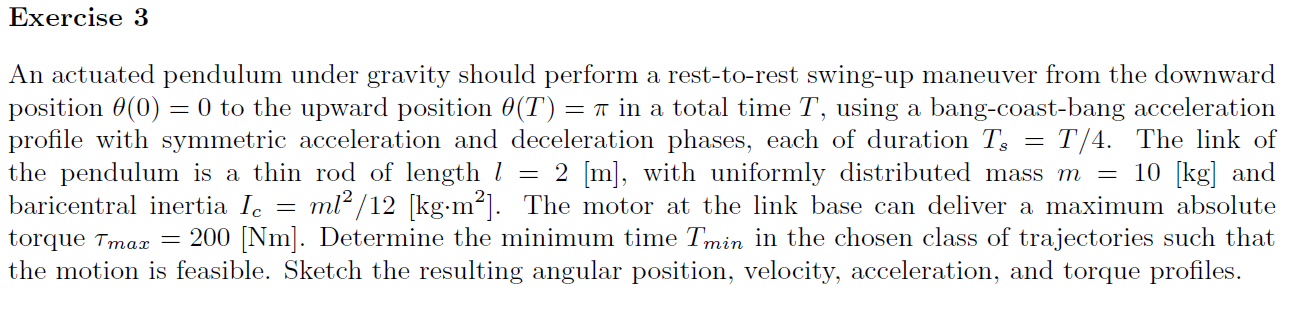

% clear all, clc, close all
% % This part is isolated from previous sectionclear;clc
% 
% % syms k q1(t) q2(t) q3(t)
% sigma = [1,0];
% n = length(sigma);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% q_d= sym('q_d_', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% % 
% dc = sym('dc', [n 1],'real');
% % dc(6)=dc(6)
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% 
% m_p = sym('m_p','real');
% d = sym('d','real');
% %m(2)=m(2)+m_p
% I = sym('I', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% % g=[-g0*sin(alpha_angle),-g0*cos(alpha_angle),0]';
% % g=[0,-g0*sin(alpha_angle),0]';
% g=[0,0,-g0]';
% R2Robot=['rp';'xx';sigma]    
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% 
% z.q=q;
% z.q_dot=q_dot;
% 
% z.dc=dc;
% 
% z.I=I;
% z.methodD=1%with DH table
% % z.dhTable=dhTable
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% z.l=l;
%  z.m=m;
% z.opt_expr={[l(1),dc'],[0,0,d]};
% % z.rcdefined=true;
% z.prismatic_CoM_method=[1,2];1%% normal mode onle CoM=dc(i) in %% 2 inverse mdoe CoM=q(i)-dc(i) %% for the moment only for prismatics

## computing M

% % [Pc,vc,w,T,Ti,M] = getGenericPC2(z);
% % T
% % Ti(:)
% % M
% % [C,cac,Csubs,S] = getCs(M,q,q_dot);
% % cac
% % % [C,cac,Csubs] = getCs(Msubs,q',qd')
% % tau =simplify( M*q_ddot + cac);
% % 
% % tau_=subs(tau)

% % C{:}
% % R=sym('R','real')
% % vars2replace =[q(2);q_dot(1)]
% % vars2replace_=[R;0]
% % tau_=subs(tau,vars2replace,vars2replace_)

## computing maximun aceleration

% clear all;
% close all;
% clc;
% m_=10
% l_=2
% theta_T=pi;
% theta_s_=theta_T/6
% I_=m_*l_^2/12
% g_0=9.81
% d_=l_/2
% tau_g_max_=m_*g_0*d_
% tau_max_=200
% sin(theta_s_)
% T_min=sqrt(16*I_*pi/(3*(tau_max_-tau_g_max_*sin(theta_s_))))

## bang cost bang profile

% T=sym('T','real');
% V1=sym('V1','real');
% A1=sym('A1','real');
% T_=1*T_min%1.2165;
% % T_=1.2165;
% Ts_=T_/4
% A1_=16*pi/(3*T_^2);
% Ts=T/4;
% V1=Ts*A1;
% V1_=Ts_*A1_;
% qA=[0,1]'
% qB_=[pi,pi]'
% qB=sym('qB',[2,1],'real');
% 
% I_0=1
% % [qa_piece2,T_,Ts_,t] = BangcostBangPRofile(qA(1,1),qB(1,1),V1_, A1_,T_)
% [qa_piece2,T_,Ts_,t] = BangcostBangPRofile(qA(1,1),qB(1,1),V1_, A1_,T_)
% fplot(qa_piece2(1,:),[0,T_])
% figure
% fplot(qa_piece2(2,:),[0,T_])
% figure
% fplot(qa_piece2(3,:),[0,T_])
% figure
% % [qa_piece2,T_,Ts_] = BangcostBangPRofile(qA(1,1),qB(1,1),V1_, A1_,T_)
% % tau_2=int(qa_piece2,t)

## tau 2

% tau_func=I_*qa_piece2(1,:)+tau_g_max_*sin(qa_piece2(3,:))
% fplot(tau_func,[0,T_])
% % figure
% % fplot(qa_piece2(2,:),[0,T_])
% % figure
% % fplot(qa_piece2(3,:),[0,T_])